## Q1 Demand Modelling

Q1) a) i) Building OD matrix from the data

clear
close all
% Loading data
data = load('TMMcoursework2024Q1.mat');
% data parameters
num_MSOA = height(data.MSOAdata.code);
num_OD_pairs = height(data.demandData.count);

tic
OD_matrix = sparse(data.demandData.MSOAoriginIndex, data.demandData.MSOAdestinationIndex, data.demandData.count, num_MSOA, num_MSOA);
toc

Elapsed time is 0.044668 seconds.


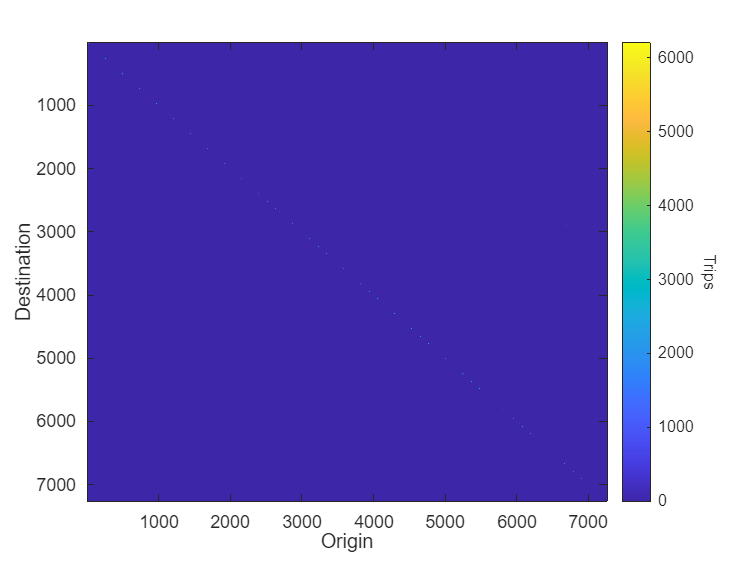

% appending OD matrix information into the data strucuture
data.MSOAdata.OD_mat = OD_matrix;


figure;
imagesc(OD_matrix);
cb = colorbar();
ylabel(cb,'Trips','Rotation',270)
xlabel("Origin")
ylabel("Destination")

Notice that the values on the diagonal, for those journeys that don't leave the MSOA area, are much higher than those inter MSOA journey counts.

% find the O_tot without the diagonal values
[m, n] = size(OD_matrix);
% Create a logical mask for the diagonal elements
diagMask = eye(m, n);
% Create a logical mask for all elements (complement of the diagonal)
nonDiagMask = ~diagMask;

data.MSOAdata.O_tot = full(sum(OD_matrix.*nonDiagMask,1))';
data.MSOAdata.D_tot = full(sum(OD_matrix.*nonDiagMask,2));


Q1) a) ii) Computing distances

% as the coordinates are given in northing and easting
% crow's flight distances can be calculated (in meters)

% Extract coordinates
e_coords = data.MSOAdata.e;
n_coords = data.MSOAdata.n;

% Create pairwise differences
[e1, e2] = meshgrid(e_coords, e_coords);
[n1, n2] = meshgrid(n_coords, n_coords);

% Calculate distances
tic
dist_mat = sqrt((e2 - e1).^2 + (n2 - n1).^2);

% Convert to sparse matrix
dist_mat = sparse(dist_mat);
toc

Elapsed time is 2.000557 seconds.


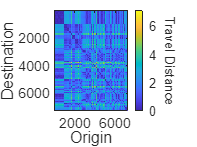

data.MSOAdata.Dist_Mat = dist_mat;

figure;
imagesc(dist_mat)
cb = colorbar();
ylabel(cb,'Travel Distance','Rotation',270)
xlabel("Origin")
ylabel("Destination")

Visualisation of the MSOA data

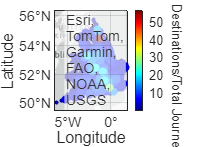

% plotting code in external function
geo_plot1(data.MSOAdata);

Interestingly there are only a few MSOA locations which are net attractors, where incoming journies outnumer outgoing jouneys.

In order to simply visualisations of the journeys we are going to focus on the Bristol MSOA locations.

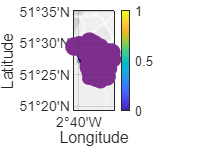

% useless plot??
geo_plot4(data.MSOAdata)

Q1) a) iii) Calculating a fit between 'inverse squared' relation between journeys between MSOA districts and the distance between them.

tic
[i,j,Trips_ij] = find(data.MSOAdata.OD_mat);
% exclude diagonal matrices
non_diag_idx = i ~= j;
i = i(non_diag_idx);
j = j(non_diag_idx);

% Compute the linear indices for the distance matrix
lin_non_diag = sub2ind(size(data.MSOAdata.Dist_Mat), i, j);

MSOA_y = log(Trips_ij(non_diag_idx)./(data.MSOAdata.O_tot(i).*data.MSOAdata.D_tot(j))); % exclude all diagonal
MSOA_x = log(full(data.MSOAdata.Dist_Mat(lin_non_diag)));
% there are values in the Dist_Mat that are non diagonal and are zero.
toc

Elapsed time is 1.434155 seconds.



% fit linear regression model
MSOA_fit = fitlm(MSOA_x, MSOA_y);

% extract alpha and c
MSOA_alpha = -MSOA_fit.Coefficients.Estimate(2);
MSOA_c = exp(MSOA_fit.Coefficients.Estimate(1));

% find predicted trips
[O_i, ~] = meshgrid(data.MSOAdata.O_tot, data.MSOAdata.O_tot);
[~, D_j] = meshgrid(data.MSOAdata.D_tot, data.MSOAdata.D_tot);

tic
MSOA_grav = (MSOA_c.*O_i.*D_j)/(full(data.MSOAdata.Dist_Mat).^(MSOA_alpha));
toc

Elapsed time is 15.261660 seconds.


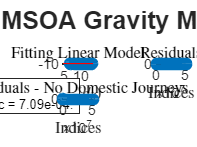


% find residual error
MSOA_res = data.MSOAdata.OD_mat - MSOA_grav;

q1_plot_5

Q1) b) i) UTLA centroids and distances

% find all MSOA per UTLA
num_UTLA = height(data.UTLAdata.code);
UTLA_e = zeros(num_UTLA,1);
UTLA_n = zeros(num_UTLA,1);

tic
for i = 1:num_UTLA
    log_arr = (data.MSOAdata.UTLAindex == i);
    idx = find(log_arr);
    UTLA_e(i) = sum(data.MSOAdata.e(idx))./numel(idx);
    UTLA_n(i) = sum(data.MSOAdata.n(idx))./numel(idx);
end
toc

Elapsed time is 0.034380 seconds.



% add UTLA_e as a structure in data.UTLAdata
data.UTLAdata.e = UTLA_e;
data.UTLAdata.n = UTLA_n;

Q1) b) ii) Origin Destination Matrix for UTLAs (inferred from summation of MSOA OD matrix)

% Extract coordinates
e_coords = data.UTLAdata.e;
n_coords = data.UTLAdata.n;

% Create pairwise differences
[e1, e2] = meshgrid(e_coords, e_coords);
[n1, n2] = meshgrid(n_coords, n_coords);

% Calculate distances
tic
UTLA_dist_mat = sqrt((e2 - e1).^2 + (n2 - n1).^2);

% Convert to sparse matrix
UTLA_dist_mat = sparse(UTLA_dist_mat);
toc

Elapsed time is 0.009029 seconds.



data.UTLAdata.Dist_Mat = UTLA_dist_mat;

UTLA_OD_mat = zeros(num_UTLA, num_UTLA);

tic
for i = 1:num_UTLA
    idx_1 = find(data.MSOAdata.UTLAindex==i); % origin
    for j = 1:num_UTLA
        idx_2 = find(data.MSOAdata.UTLAindex==j); % destination
        UTLA_OD_mat(i,j) = sum(OD_matrix(idx_1,idx_2), "all");
    end
end
toc

Elapsed time is 2.068437 seconds.


data.UTLAdata.OD_mat = UTLA_OD_mat;
% find the O_tot without the diagonal values
[m, n] = size(UTLA_OD_mat);
% Create a logical mask for the diagonal elements
diagMask = eye(m, n);
% Create a logical mask for all elements (complement of the diagonal)
nonDiagMask = ~diagMask;
lin_non_diag_idx = find(nonDiagMask);

data.UTLAdata.O_tot = full(sum(UTLA_OD_mat.*nonDiagMask,1))';
data.UTLAdata.D_tot = full(sum(UTLA_OD_mat.*nonDiagMask,2));


Visualisation of ULTA data

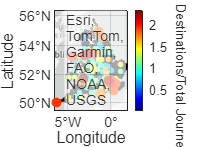

geo_plot3(data.MSOAdata, data.UTLAdata);

Q1) c)

tic
[i,j,Trips_ij] = find(full(data.UTLAdata.OD_mat));
% exclude diagonal matrices
non_diag_idx = i ~= j;
i = i(non_diag_idx);
j = j(non_diag_idx);
% [i, j, dist_vals] = find(full(data.MSOAdata.Dist_Mat)); % Non-zero indices and values

% Compute the linear indices for the distance matrix
lin_non_diag = sub2ind(size(data.UTLAdata.Dist_Mat), i, j);

UTLA_y = log(Trips_ij(non_diag_idx)./(data.UTLAdata.O_tot(i).*data.UTLAdata.D_tot(j))); % exclude all diagonal
UTLA_x = log(full(data.UTLAdata.Dist_Mat(lin_non_diag)));
toc

Elapsed time is 0.029138 seconds.


% fit linear regression model
UTLA_fit = fitlm(UTLA_x, UTLA_y);

% extract alpha and c
UTLA_alpha = -UTLA_fit.Coefficients.Estimate(2);
UTLA_c = exp(UTLA_fit.Coefficients.Estimate(1));

%% UNCONSTRAINED MODEL
% find predicted trips
[O_i, ~] = meshgrid(data.UTLAdata.O_tot, data.UTLAdata.O_tot);
[~, D_j] = meshgrid(data.UTLAdata.D_tot, data.UTLAdata.D_tot);

tic
UTLA_grav = (UTLA_c.*O_i.*D_j)/(full(data.UTLAdata.Dist_Mat).^(UTLA_alpha));
toc

Elapsed time is 0.010423 seconds.


UTLA_res = data.UTLAdata.OD_mat - UTLA_grav;


## ORIGIN CONSTRAINED

The unconstrained model is scaled by 1/ (sum of destination x impedence function)

As gravity model impedence function is defined as 1/dij^-alpha

[~, D_k] = meshgrid(data.UTLAdata.D_tot, data.UTLAdata.D_tot);

OC_sum = D_k.*(1./(full(data.UTLAdata.Dist_Mat).^(UTLA_alpha)));
% cannot divide by zero value so get rid of diagonals
OC_sum(find(diagMask)) = 0;
scale_OC = 1./sum(OC_sum,1);
scale_OC = scale_OC.*(~isnan(scale_OC));

UTLA_OC = UTLA_grav .* scale_OC;

% calculate residuals for OC
UTLA_res_OC = data.UTLAdata.OD_mat - UTLA_OC;

## DESTINATION CONSTRAINED

[~, O_k] = meshgrid(data.UTLAdata.O_tot, data.UTLAdata.O_tot);

DC_sum = O_k.*(1./(full(data.UTLAdata.Dist_Mat).^(UTLA_alpha)));
% cannot divide by zero value so get rid of diagonals
DC_sum(find(diagMask)) = 0;
scale_DC = 1./sum(DC_sum,1);
scale_DC = scale_DC.*(~isnan(scale_DC));

UTLA_DC = UTLA_grav .* scale_DC;

% calculate residuals for DC
UTLA_res_DC = data.UTLAdata.OD_mat - UTLA_DC;

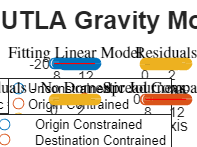

q1_plot_6